# Laboratorium 3

# Analiza harmoniczna - część 1

Janusz Pawlicki

## 1 Wstęp - Analiza harmoniczna sygnałów

### 1.1 Rozwijanie sygnałów w szereg Fouriera

Jednym z podstawowych narzędzi matematycznych pozwalających na badanie rzeczywistych sygnałów ciągłych jest fourierowska analiza harmoniczna polegająca na rozwinięciu nieskończonego okresowego sygnału ciągłego w tzw. szereg Fourier'a. Umożliwia ona m.in. analizę zachowania liniowych i stacjonarnych układów dynamicznych (mechanicznych, elektrycznych i innych) w stanie ustalonym podczas pobudzenia sygnałem ciągłym okresowym. Pozwala modelować proces konwersji sygnału analogowego (ciągłego) na postać cyfrową tj. przetwarzanie A/C (Analog/Cyfra). Jest również wykorzystywana w opisywaniu procesu modulacji oraz ocenie zniekształceń sygnałów.

Na potrzeby ćwiczenia przyjmujemy, że funkcja x(t) opisująca sygnał ciągły ma charakter rzeczywisty (a nie zespolony) i spełnia warunek x(t) = x∗(t) oraz warunki Dirichleta:

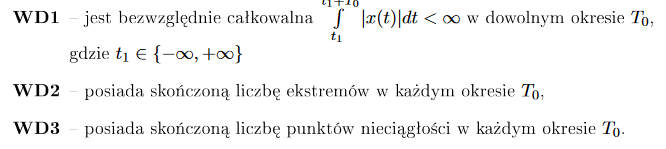

Rozwini¦cie sygnału w szereg Fouriera i transformacja odwrotna opisana może być za pomocą jednej z trzech postaci: wykładniczej (1, 2), fazowej (3, 4) i trygonometrycznej (5, 6):

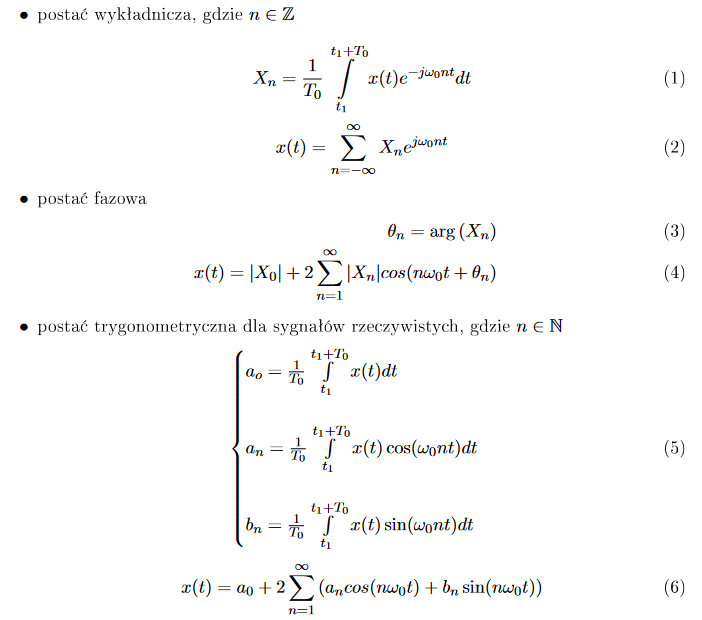

### 1.2 Współczynnik zawartości harmonicznych

Jednym z parametrów charakteryzujących sygnały ciągłe jest współczynnik zawartości harmonicznych (11) THD (ang. Total Harmonic Distortion) opisujący stopień odkształcenia sygnału od idelanego przebiegu sinusoidalnego. Przesunięcie fazowe nie ma znaczenia ponieważ do jego wyliczenia wykorzystuje się skuteczne wartości RMS (ang. Root Mean Square) poszczególnych składowych funkcji harmonicznych.

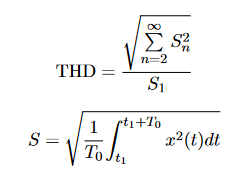

## 2 Przebieg laboratorium - zadania

## Zadanie 1

Stosując symboliczną reprezentację zmiennych i funkcji wygeneruj jeden okres przebiegu trójkątnego i określ jego podstawowe parametry w dziedznie czasu.

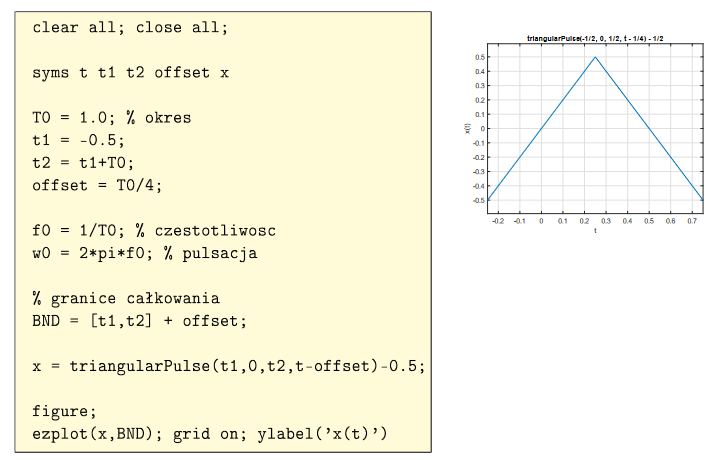

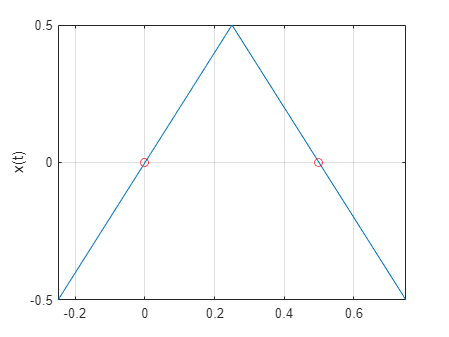

syms t t1 t2 offset x

T0 = 1.0;
t1 = -0.5;
t2 = t1 + T0;

offset = T0/4;

f0 = 1/T0;

w0 = 2*pi*f0;

BND = [t1,t2] + offset;

x = triangularPulse(t1, 0.0, t2, t-offset) - 0.5;

figure
fplot(x, BND), grid on, ylabel('x(t)')

hold on

plot(0, 0, 'ro')
plot(0.5, 0, 'ro')

## Zadanie 2

Wyznacz współczynniki zespolonego szeregu Fouriera Xn dla 16-tu pierwszych funkcji bazowych i oznacz ich wartości na wykresie. W sprawozdaniu umieść uzyskany wykres zespolonych współcznników szeregu Fouriera.

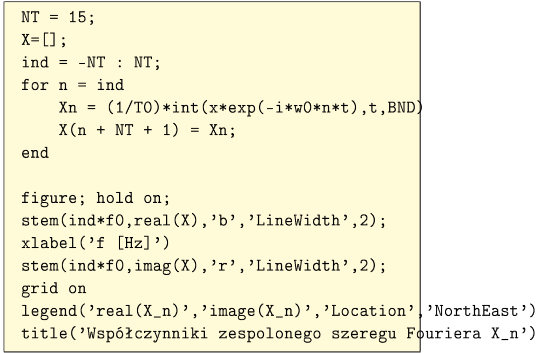

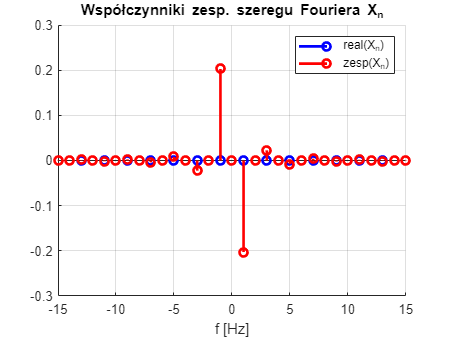

NT = 15;

X=[];

ind = -NT:NT;

for n = ind
    Xn = (1/T0)*int(x*exp(-1i*w0*n*t),t,BND);
    X(n + NT + 1) = Xn;
end

figure

hold on

stem(ind*f0, real(X),'b','LineWidth',2);

xlabel('f [Hz]')

stem(ind*f0, imag(X),'r','LineWidth',2);

grid on

legend('real(X_n)','zesp(X_n)','Location','NorthEast'),

title('Współczynniki zesp. szeregu Fouriera X_n')

## Zadanie 3

Wyznacz współczynniki an i bn trygonometryczne szeregu dla 15-tu pierwszych częstotliwości harmonicznych oraz składowej stałej a0 zgodnie ze wzorem (5) i przypisz je do wektorów typu rzeczywistego a oraz b wzroując się na przykładzie z rys. 2. Pokaż je na wykresie z zachowaniem skali częstotliwości (wykres umieść w sprawozdaniu).

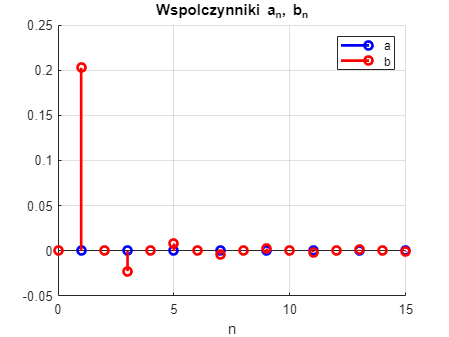

NT = 0:15;

a=[];
b=[];

for n = NT
    a(n+1) = (1/T0)*int(x*cos(w0*n*t),t,BND);
    b(n+1) = (1/T0)*int(x*sin(w0*n*t),t,BND);
end

figure; 

grid on

hold on

stem(NT,a,'b','LineWidth',2);

xlabel('n')

stem(NT,b,'r','LineWidth',2);

legend('a','b'),

title('Wspolczynniki a_n, b_n')

hold off

Wektor a odpowiada części rzeczywistej i jest równy 0.

Wektor b odpowiada części urojonej (znak został zmieniony na przeciwny).

## Zadanie 4

Na podstawie uzyskanych współczynników a0, an i bn odtwórz 3 okresy przebiegu wejściowego w reprezentacji czasowej.

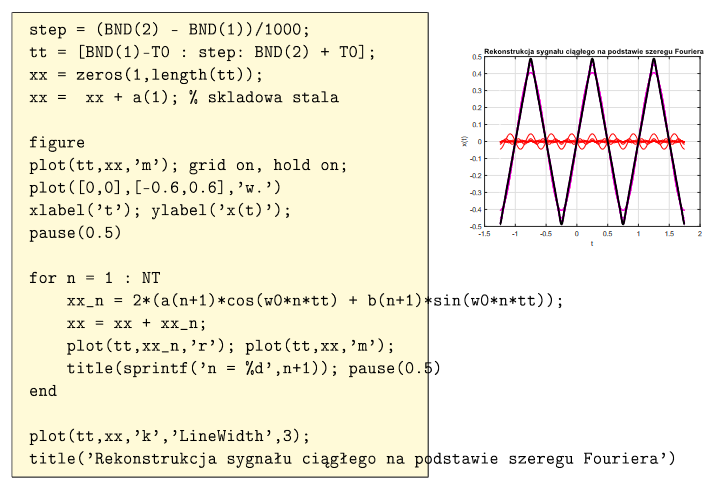

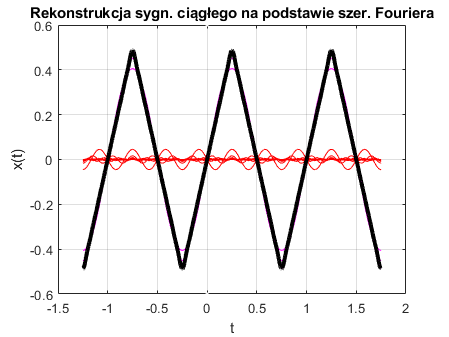

step = (BND(2)-BND(1))/1000;

tt = [BND(1)-T0 : step : BND(2) + T0];

xx = zeros(1,length(tt));
xx = xx + a(1);

figure;

plot(tt,xx,'m')

grid on 

hold on

plot([0, 0],[-0.6, 0.6], 'w.'),

xlabel('t'); ylabel('x(t)');

pause(0.5)

for n = NT
    xx_n = 2*(a(n+1)*cos(w0*n*tt) + b(n+1)*sin(w0*n*tt));
    xx = xx + xx_n;
    plot(tt,xx_n,'r');
    plot(tt,xx,'m');
    title(sprintf('n = %d',n+1));
    pause(0.5)
end

plot(tt,xx,'k','LineWidth',3);
title('Rekonstrukcja sygn. ciągłego na podstawie szer. Fouriera')

hold off

## Zadanie domowe

Wyznacz w sposób analityczny wzór (na papierze) na współczynniki szeregu Fouriera wybranego przebiegu (innego niż przebieg sinusoidalny) jego wartość skuteczną oraz współczynnik zniekształceń harmonicznych THD. W sprawozdaniu umieść:

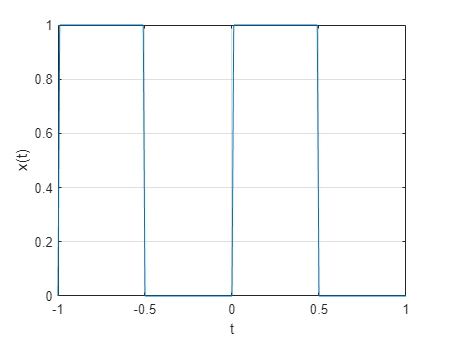

funkcja